clc
clear all
num = [10];
den = [1 25 2 6];

tfun = tf(num,den)

tfun =
 
            10
  ----------------------
  s^3 + 25 s^2 + 2 s + 6
 
Continuous-time transfer function.




control = pidtune(tfun, 'PID')

control =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 7.66, Ki = 1.97, Kd = 7.47
 
Continuous-time PID controller in parallel form.



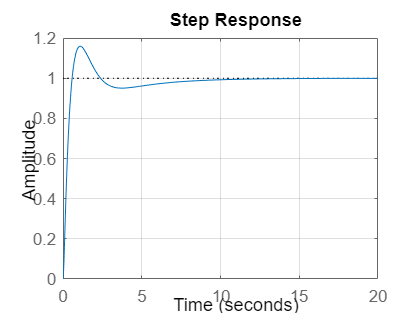


graf = feedback(tfun*control,1);

step(graf)
grid on

## Desarrollo en tiempo discreto.

funDis = zpk(num, den, 1)

funDis =
 
         10 (s-10)
  ------------------------
  (s-1) (s-2) (s-6) (s-25)
 
Continuous-time zero/pole/gain model.



controlDis = pidtune(funDis, 'PID')

controlDis =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -0.214, Ki = -0.00249, Kd = -4.58
 
Continuous-time PID controller in parallel form.




grafDis = feedback(tfun*control,1);

step(grafDis)
grid on